# Part 1

L1rerx = 0;
L2rerx = 250000;
L1slope = 1.8;
L2slope = 1.2;
L1alpha = 2/pi*atan(L1slope)

L1alpha = 0.6772

L2alpha = 2/pi*atan(L2slope)

L2alpha = 0.5577


w0 = 2*pi*100; %Hz

L1K = 175000 - 1i*250000 - L1rerx*(1i*w0)^L1alpha

L1K = 1.7500e+05 - 2.5000e+05i

L2K = 415000 - 1i*250000 - L2rerx*(1i*w0)^L2alpha

L2K = -5.4038e+06 - 7.2326e+06i

w = 1000*2*pi;
L1Ztot = abs(50000 +L1K/(1i*w)^L1alpha)*0.001

L1Ztot = 49.6476

L2Ztot = abs(250000 +L2K/(1i*w)^L2alpha)*0.001

L2Ztot = 181.3785

# Part 2

f_sampling = 1000 %Hz

f_sampling = 1000

load("ecogdatasnippet.mat")
Channels_average = mean(refChannels.*ecogData)

Channels_average =    98.9021  187.3276  264.4698  239.4771  204.8607  168.9883   91.1633   71.0448  -22.6289 -118.1794 -200.0333 -201.2909 -161.8443 -129.5732  -67.0740  -34.4716   29.3232  109.1784  211.5169  240.9411  211.1359  176.7620  130.9531   66.8674   12.8995  -81.9049 -140.6424 -219.1216 -196.5633 -161.6557 -125.5409  -61.7458  -47.6826   31.7841  115.4286  222.8852  228.2117  201.1586  168.6927   93.7591   52.9510  -18.4068 -107.9862 -179.2667 -217.8469 -182.7578 -153.9310 -101.4690  -49.2359  -12.2112


Channel_29 = ecogData(29,:)-Channels_average

Channel_29 =    58.9979  114.5391  270.8302  229.4563  155.8727   82.4451  -49.0633 -154.4448 -205.4711 -249.2206 -383.5333 -433.7424 -353.3891 -290.7268 -170.8594  -34.1951   29.1102   68.2216  167.8497  310.4922  244.0641  197.2047  131.7802   -5.4341  -99.1995 -118.9284 -137.6576 -288.5451 -275.0034 -211.1109 -150.2924  -35.6208   77.7159  113.3159  150.5714  311.6815  389.0883  307.2081  268.7740  156.1076    6.9823  -70.3932 -126.0805 -189.2000 -331.5531 -246.4422 -193.2357 -125.5977  -22.3974   40.5779



fs = 250;
Ch29_LF = bandpass(Channel_29, [1 5], fs);
Ch29_MF = bandpass(Channel_29, [6 50], fs);
Ch29_HF = bandpass(Channel_29, [54 250], fs);

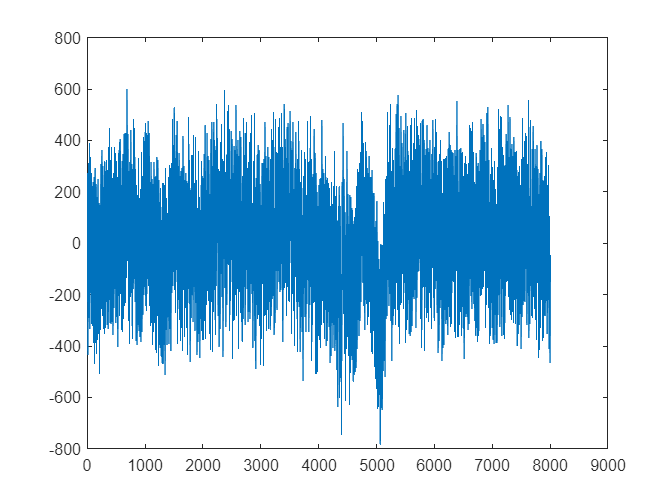

plot(Channel_29)

% plot(Ch29_LF)
% hold on
% plot(Ch29_MF)
% plot(Ch29_HF)
% hold off


LF_power = smooth((Ch29_LF).^2, 100);
MF_power = smooth((Ch29_MF).^2, 100);
HF_power = smooth((Ch29_HF).^2, 100);

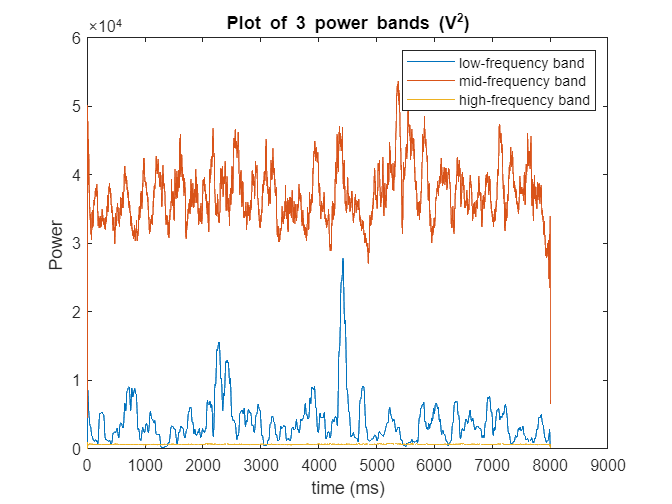

TS = 1000;
plot(LF_power)
hold on

plot(MF_power)
plot(HF_power)
title("Plot of 3 power bands (V^2)")
xlabel("time (ms)")
ylabel("Power ")
legend("low-frequency band", "mid-frequency band", "high-frequency band")
hold off

# Part 3

load("spikes.mat")

meann = mean(spikes);
sd = std(spikes);

spikes_norm = (spikes-meann)./sd;
[w, u, lambda] = pca(spikes_norm);
var = cumsum(lambda,1)/max(cumsum(lambda,1))

var =     0.4005
    0.5800
    0.7046
    0.7794
    0.8188
    0.8538
    0.8779
    0.8976
    0.9133
    0.9267


k = 9

k = 9

%spike number 5
k =9;
spike_num =5

spike_num = 5

u_new = u(spike_num,1:k)

u_new =     4.4382    5.6794   -2.9584    0.1032   -0.5597   -1.2509   -0.1237    0.1047    0.9976


w_new= w(:,1:k)

w_new =     0.0585    0.0917    0.1523   -0.1052    0.3862    0.4695    0.4775    0.3051    0.3709
    0.0694    0.1057    0.2268   -0.2082    0.3778    0.3452    0.0381   -0.1130   -0.3565
    0.0867    0.1019    0.2820   -0.3084    0.1976    0.0494   -0.2742   -0.2056   -0.2076
    0.1009    0.1167    0.3099   -0.3009    0.0470   -0.1038   -0.3062   -0.1356    0.0320
    0.1170    0.1169    0.3157   -0.2542   -0.1118   -0.2039   -0.1502    0.0466    0.2629
    0.1421    0.1099    0.2973   -0.1652   -0.2583   -0.1909    0.0993    0.1692    0.2025
    0.1677    0.1054    0.2562   -0.0451   -0.3426   -0.0918    0.2939    0.1555   -0.0378
    0.1666    0.1589    0.1913    0.1133   -0.3292    0.0577    0.3212   -0.0094   -0.2794
    0.0988    0.2751    0.1104    0.2663   -0.1761    0.1557    0.1295   -0.1887   -0.2396
   -0.0530    0.2976    0.0958    0.3272    0.0882    0.0564   -0.1078   -0.1362   -0.0205


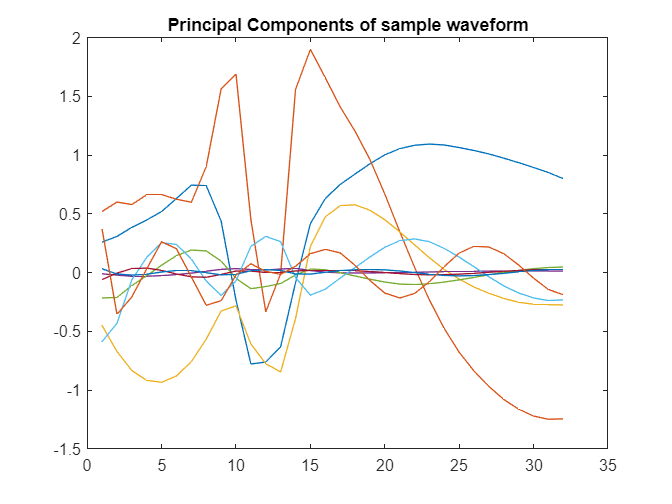

figure
dat = w_new.*u_new;
for i = [1:1:k]
    plot(dat(:,i))
    hold on
end
title("Principal Components of sample waveform")
hold off

% plot(spikes_norm(spike_num,:))
% hold on
% plot(sum(dat,2))
% hold off

k = 32

k = 32

%spike number 5
u5 = u(5,1:k);
w5 = w(:,1:k);
dat = w5.*u5;
reconstruct = sum(dat,2);
reconstruct_unnorm =  reconstruct.*sd'+meann'

reconstruct_unnorm =    -0.0000
  -19.0549
   -7.3679
    4.6783
   10.4405
   11.8989
    8.4293
   -0.9848
   -8.5616
  -26.2665



figure
plot(spikes(5,:))
hold on

plot(reconstruct_unnorm)
k = 6

k = 6

u5 = u(5,1:k);
w5 = w(:,1:k);
dat = w5.*u5;
reconstruct = sum(dat,2);
reconstruct_unnorm =  reconstruct.*sd'+meann'

reconstruct_unnorm =    -5.4204
   -8.2755
   -5.5974
    0.4505
    5.0379
    8.0879
    8.5323
    8.1203
    1.8097
  -26.4399


plot(reconstruct_unnorm)

k = 4

k = 4

u5 = u(5,1:k);
w5 = w(:,1:k);
dat = w5.*u5;
reconstruct = sum(dat,2);
reconstruct_unnorm =  reconstruct.*sd'+meann'

reconstruct_unnorm =     1.6805
    0.7819
   -2.4764
   -1.4792
   -1.1112
    0.5863
    2.5112
    6.0185
    3.4858
  -24.4622


plot(reconstruct_unnorm)
legend('original spike','32 components', '6 components', '4 components')
title('Reconstruction of spike with principle components')
hold off

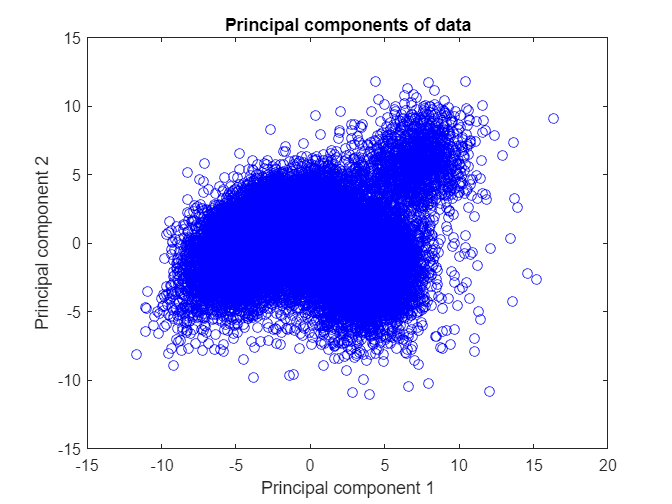

plot(u(:,1), u(:,2), 'bo')
title('Principal components of data')
xlabel('Principal component 1')
ylabel('Principal component 2')